% Objective function coefficients
f = [1; 1];

% Inequality constraints (Ax <= b)
A = [ -1, 2; 1, 5];
b = [ 5; 12];

Aeq = [1, 2];
beq = 3;

% Lower bounds on variables
lb = [0; 0];
ub = [inf,inf];

% Solve the linear programming problem
[x, z] = linprog(f, A, b, Aeq,beq , lb, ub);

找到最优解。




% Display the results
fprintf('Optimal Solution:\n');

Optimal Solution:


fprintf('x1 = %.2f\n', x(1));

x1 = 0.00


fprintf('x2 = %.2f\n', x(2));

x2 = 1.50


fprintf('Optimal Objective Value (z) = %.2f\n', z);

Optimal Objective Value (z) = 1.50



c_bv = [1 0 0]

c_bv =      1     0     0



B_2 = [
    2 0 0;
    2 1 0;
    5 0 1]

B_2 =      2     0     0
     2     1     0
     5     0     1



B_2_inverse = inv(B_2)

B_2_inverse =     0.5000         0         0
   -1.0000    1.0000         0
   -2.5000         0    1.0000





c_bv*B_2_inverse

ans =     0.5000         0         0






B_3 = [
    4 1;
    5 2]

B_3 =      4     1
     5     2



B_3_inverse = inv(B_3)

B_3_inverse =     0.6667   -0.3333
   -1.6667    1.3333



%b = 0;
%b_constraint = [b 10]


3.3/0.67

ans = 4.9254


13.3/1.67

ans = 7.9641

% Define the symbolic variables
syms x1 x2

% Define the equations
eq1 = 4*x1 + x2 == 7;
eq2 = 5*x1 + 2*x2 == 10;

% Solve the system of equations for x1 and x2
sol = solve([eq1, eq2], [x1, x2]);

% Display the solution
x1_solution = sol.x1;
x2_solution = sol.x2;

fprintf('Intersection Point:\n');

Intersection Point:


fprintf('x1 = %f\n', x1_solution);

x1 = 1.333333


fprintf('x2 = %f\n', x2_solution);

x2 = 1.666667


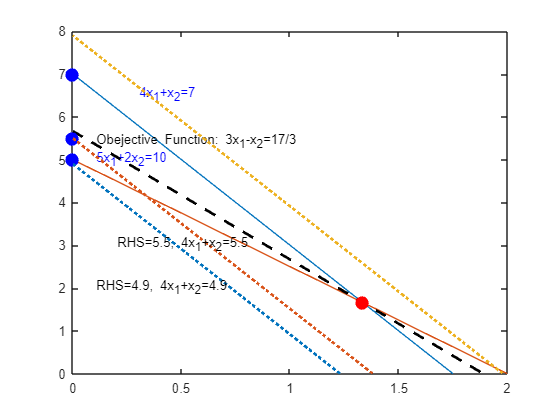


%clc;
clear;
close all;
L1 = [0, 7;7/4, 0];
plot(L1(:,1),L1(:,2));hold on
text(0.3,6.5,'4x_1+x_2=7','color','b');

L2 = [0, 5;2, 0];
plot(L2(:,1),L2(:,2));hold on
text(0.1,5,'5x_1+2x_2=10','color','b');

%L3 = [0, 17/3;17/9, 0];
%plot(L3(:,1),L3(:,2));hold on
%text(0.5,3.4,'3x_1-x_2=z','color','b');



%x=[0 17/9 4/3 0]';%% Get the equation intersection points(extrem point)
%y=[0 0 5/3 5]';
%fill(x,y,'r')
%xlabel('x_1')
%ylabel('x_2')
%axis([0 3 -0.2 4])

%%z1 = [0,2;2,1];
%%plot(z1(:,1),z1(:,2),'k--','Linewidth',2);hold on
%%text(1.5,1.5,'z1=4');

%%z2 = [1,9/4; 3,5/4];
%%plot(z2(:,1),z2(:,2),'k--','Linewidth',2);hold on
%%text(2,1.4,'z2=5.5');

%%z3 = [0.5,13/4;4,3/2];
%%plot(z3(:,1),z3(:,2),'k--','Linewidth',2);hold on
%%text(2.5,2,'z3=7');

alpha = [0, 17/3;17/9, 0];
plot(alpha(:,1),alpha(:,2),'k--','Linewidth',2);hold on
text(0.1,5.4,'Obejective Function: 3x_1-x_2=17/3');

% Highlight a specific point by adding a red marker
hold on;  % This allows you to overlay multiple plots on the same figure
specific_x = 0;  % x-coordinate of the specific point
specific_y = 7;  % y-coordinate of the specific point
scatter(specific_x, specific_y, 100, 'b', 'filled');  % 'b' for blue color

% Highlight a specific point by adding a red marker
hold on;  % This allows you to overlay multiple plots on the same figure
specific_x = 4/3;  % x-coordinate of the specific point
specific_y = 5/3;  % y-coordinate of the specific point
scatter(specific_x, specific_y, 100, 'r', 'filled');  % 'b' for blue color

% Highlight a specific point by adding a red marker
hold on;  % This allows you to overlay multiple plots on the same figure
specific_x = 0;  % x-coordinate of the specific point
specific_y = 5;  % y-coordinate of the specific point
scatter(specific_x, specific_y, 100, 'b', 'filled');  % 'b' for blue color

% Highlight a specific point by adding a red marker
hold on;  % This allows you to overlay multiple plots on the same figure
specific_x = 0;  % x-coordinate of the specific point
specific_y = 5.5;  % y-coordinate of the specific point
scatter(specific_x, specific_y, 100, 'b', 'filled');  % 'b' for blue color

RHS2 = [1.23, 0; 0,4.9];
plot(RHS2(:,1),RHS2(:,2),':','Linewidth',2);hold on
text(0.1,2,'RHS=4.9, 4x_1+x_2=4.9');

RHS3 = [1.38, 0; 0, 5.5];
plot(RHS3(:,1),RHS3(:,2),':','Linewidth',2);hold on
text(0.2,3,'RHS=5.5, 4x_1+x_2=5.5');


RHS4 = [1.98,0;0,7.9];
plot(RHS4(:,1),RHS4(:,2),':','Linewidth',2);hold on
text(2.6,1.5,'RHS=7.9, 4x_1+x_2=7.9');

% Define the objective function coefficients (c)
c = [-3; -1];  % Minus sign because linprog minimizes by default

% Define the inequality matrix (A) and right-hand side (b)
A = [-4, -1; -5, -2];  % Coefficients of x1 and x2 in the inequalities
b = [-5; -10];  % Right-hand side values

% Define the lower bounds for x1 and x2
lb = [0; 0];

% Solve the LP problem using linprog
[x, z] = linprog(c, [], [], A, b, lb);

找到最优解。




% Display the results
fprintf('Optimal Solution:\n');

Optimal Solution:


fprintf('x1* = %.2f\n', x(1));

x1* = 0.00


fprintf('x2* = %.2f\n', x(2));

x2* = 5.00


fprintf('Optimal Objective Value (z*) = %.2f\n', -z);  % Note the minus sign

Optimal Objective Value (z*) = 5.00


% 验算
% Define the objective function coefficients
f = [1; 1];

% Define the inequality constraints in the form A*x <= b
A = [-1, -2; 1, -2; -1, -5];
b = [5; 5; 12];

% Define the equality constraint in the form Aeq*x = beq
Aeq = [1, 2];
beq = 3;

% Define the lower and upper bounds for x
lb = [0; 0];
ub = [];

% Use the linprog function to solve the linear programming problem
[x, z] = linprog(f, A, b, Aeq, beq, lb, ub);

找到最优解。




% Display the results
fprintf('Optimal solution:\n');

Optimal solution:


fprintf('x1 = %.2f\n', x(1));

x1 = 0.00


fprintf('x2 = %.2f\n', x(2));

x2 = 1.50


fprintf('Optimal objective value: %.2f\n', z);

Optimal objective value: 1.50


问题无界。



Dual optimal solution:


索引超过数组元素的数量。索引不能超过 0。